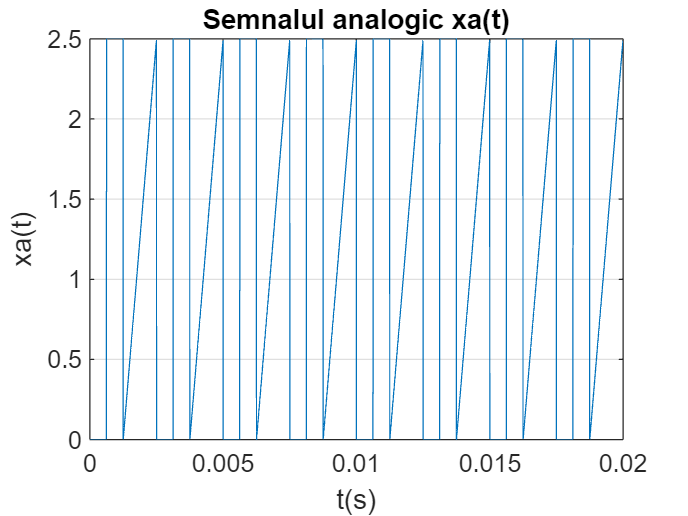

%% PARTEA 1

clear;
clc;
close all;

% Parametrii semnalului analogic
F0 = 400;
A = 2.5;
        
% Parametrii discretizarii
Fs = 16000;
FsA = Fs*10;
Tmax = 0.02;

% Parametrii FFT
Nfft = 1024;

% Obtinerea Semnalului Analogic
[t, semnal_an] = semnal_an(F0,A,Tmax,FsA);

% Reprezentarea Semnalului Analogic
figure();
plot(t,semnal_an);
grid on;
title("Semnalul analogic xa(t)");
xlabel("t(s)");
ylabel("xa(t)");

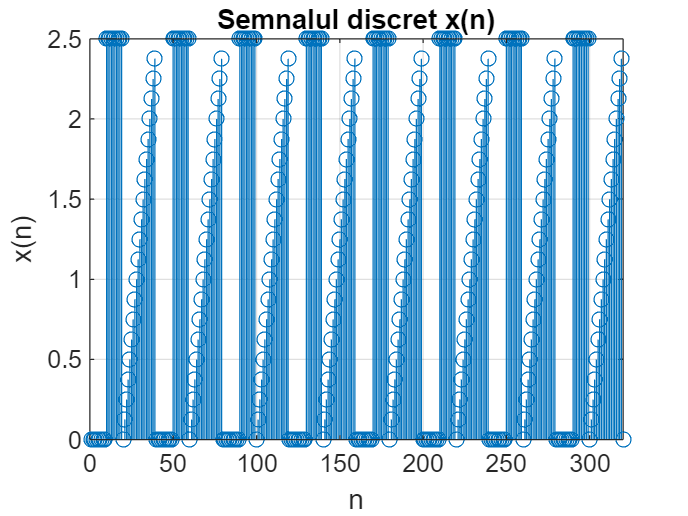


% Obtinerea Semnalului Discret
[n, semnal_dig] = semnal_dig(F0,A,Tmax,Fs);

% Reprezentarea Semnalului Discret
figure();
stem(n,semnal_dig);
grid on;
title("Semnalul discret x(n)");
xlabel("n");
ylabel("x(n)");

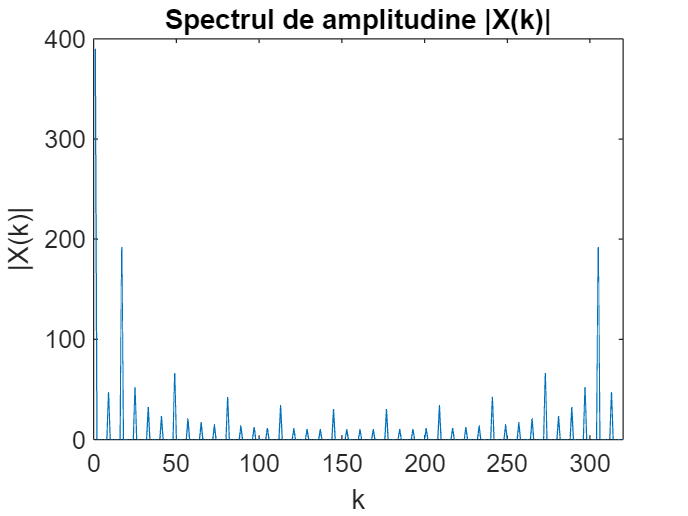

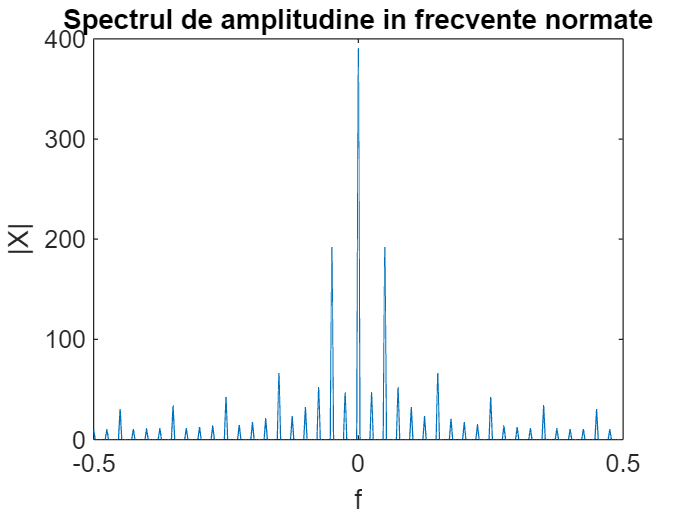

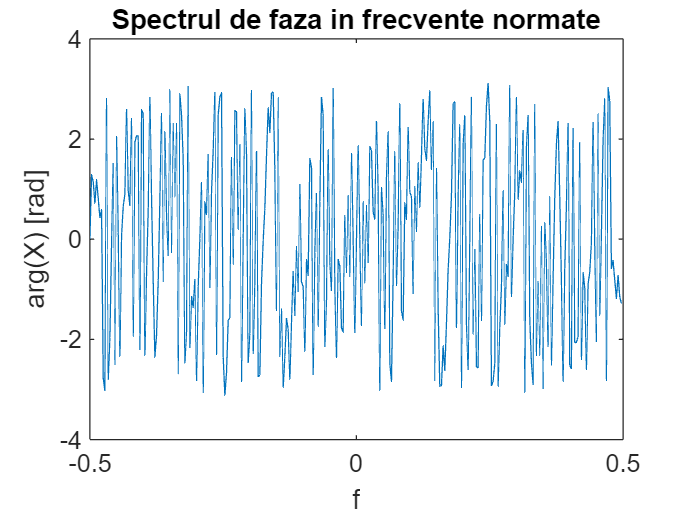

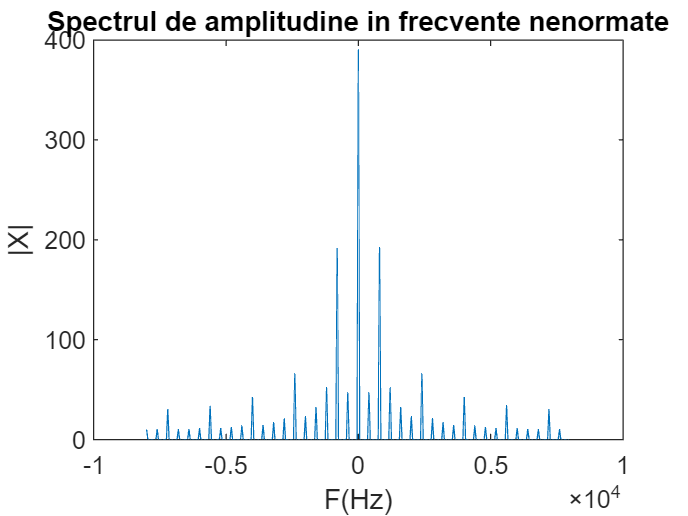


% Aflarea parametrilor ceruti la I. a)
Nes = length(n);
N = Fs/F0;
P = Nes/N;

% Analiza Fourier in discret pentru Nfft = Nes
TFD1 = Fourier_Analysis(semnal_dig,Fs);

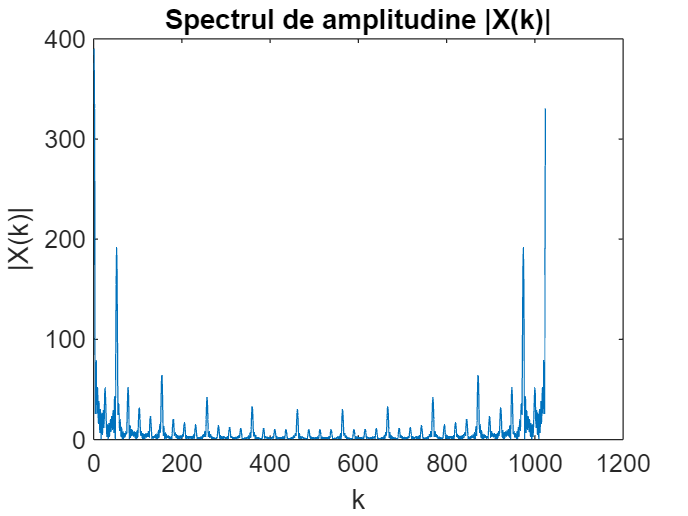

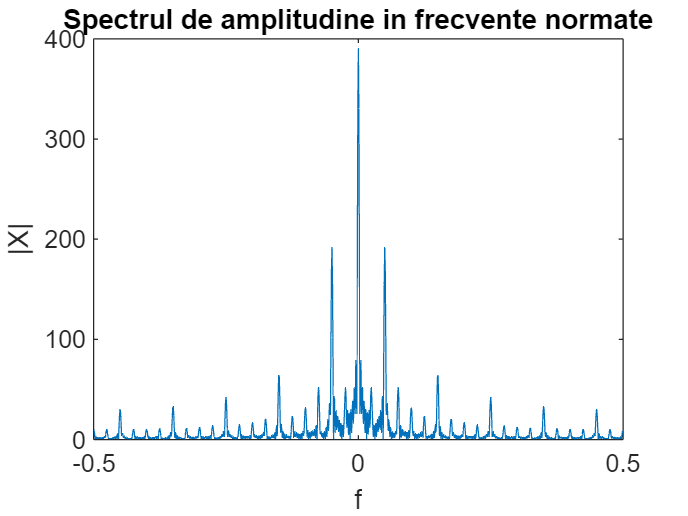

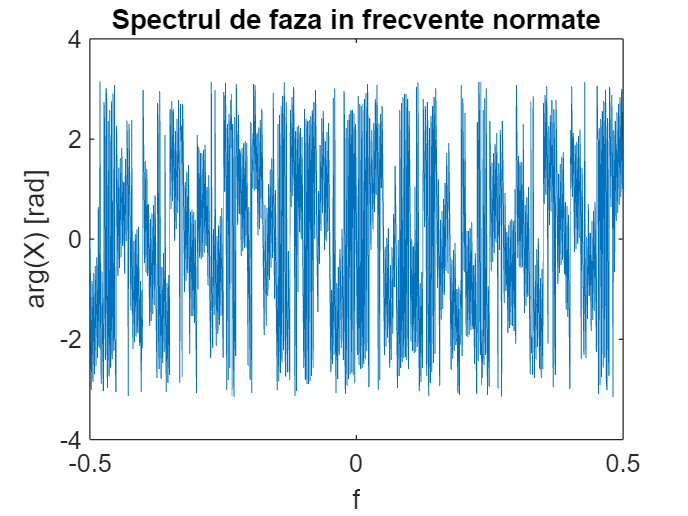

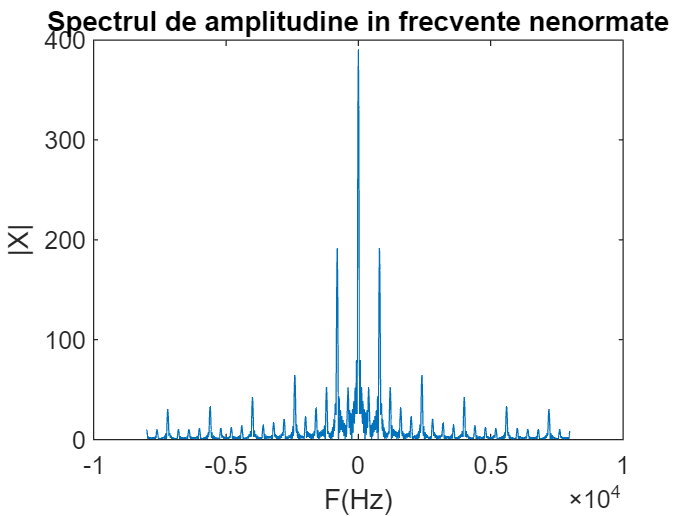


% Analiza Fourier in discret pentru Nfft = 1024 (din tabel)
TFD2 = Fourier_Analysis(semnal_dig, Fs, Nfft);

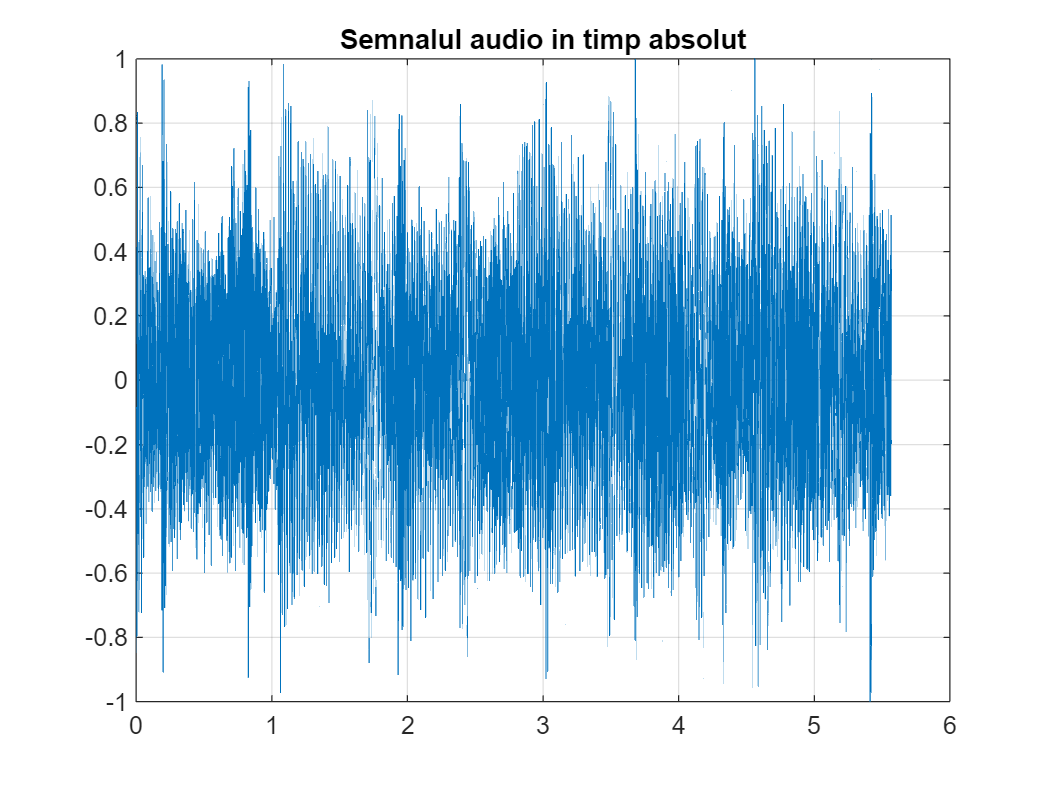

%% PARTEA 2

clear;
clc;
close all;

% Redefinire parametri semnal de la a)
F0 = 400;
A = 0.15;
Nfft = 1024;

% Accesare semnal audio - Selecteaza semnalul dorit
[w, Fss] = audioread("Goodnight_Kiss_Converted.wav");
L = length(w);
ts = 0:1/Fss:(L-1)/Fss;

% Reprezentare semnal audio in timp absolut
figure();
plot(ts, w);
grid on;
title("Semnalul audio in timp absolut");

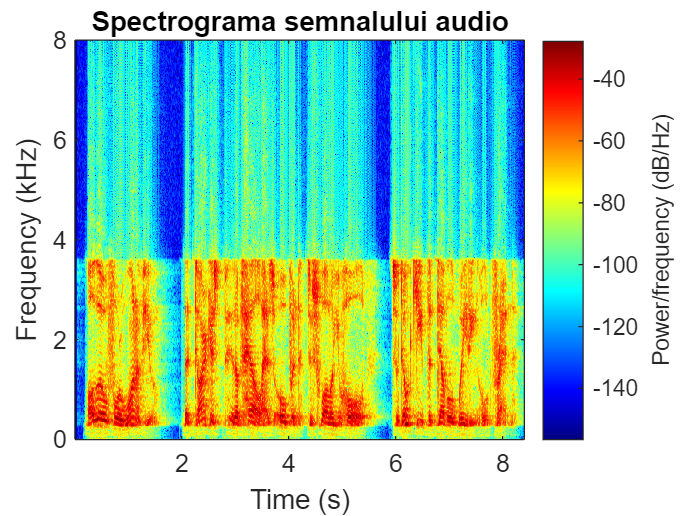


% Reprezentare spectrograma semnal audio
figure();
spectrogram(w, 512, 256, Nfft, Fss, 'yaxis'); 
colormap("jet");
title("Spectrograma semnalului audio");


% Definirea semnalului s(n)
Tmax = L/Fss; 
[n, x] = semnal_dig(F0,A,Tmax,Fss);
s = w' + x;

% Reprezentare spectrograma s(n)
figure();
spectrogram(s, 512, 256, Nfft, Fss, 'yaxis');
colormap("jet");
title("Spectrograma semnalului s");

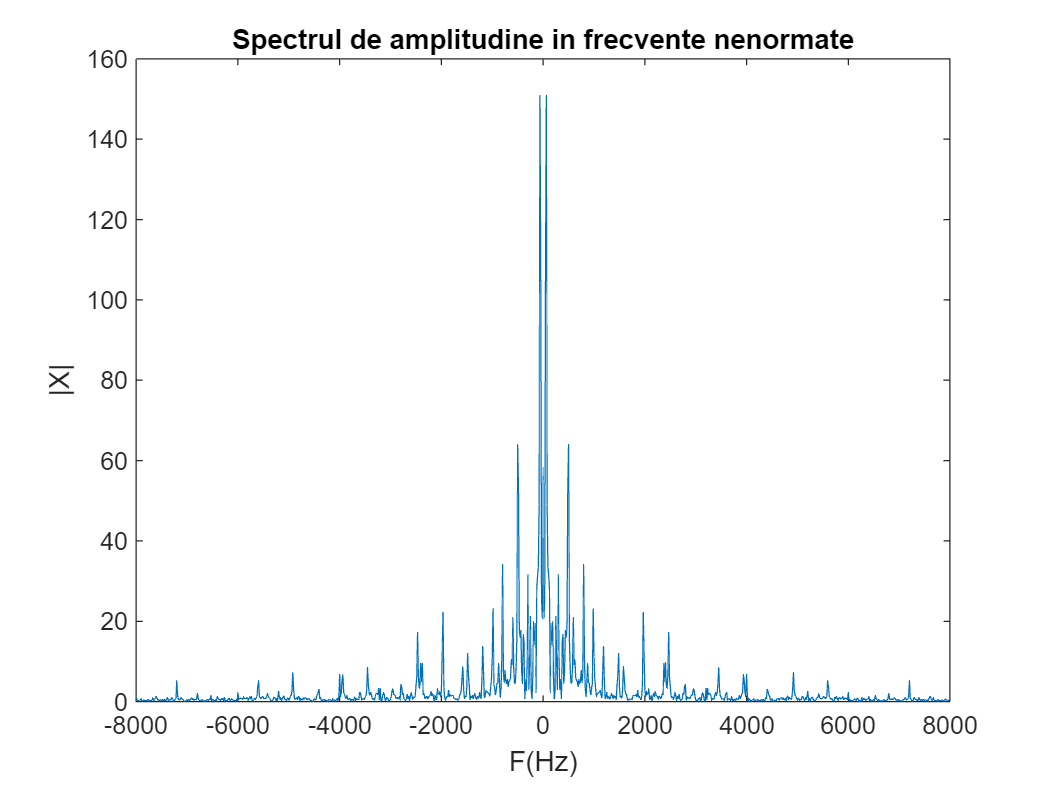


% Transformata Fourier a semnalului s(n)
S = fft(s,Nfft);

% Spectrul de amplitudine in frecvente nenormate
Fs2 = -Fss/2: Fss/Nfft: Fss/2 - Fss/Nfft;
figure();
plot(Fs2, fftshift(abs(S)));
title("Spectrul de amplitudine in frecvente nenormate");
xlabel('F(Hz)');
ylabel('|X|');


% Determinarea Zerourilor
w0 = 2*pi*F0/Fss;
z1 = exp(1j*w0);
z2 = exp(1j*2*w0);
z3 = exp(1j*3*w0);
z4 = exp(1j*4*w0);

% Determinare Polilor
r = 0.9995;
p1 = r*z1;
p2 = r*z2;
p3 = r*z3;
p4 = r*z4;

% Vectorii zerourilor si ai polilor

z = [z1, conj(z1), z2, conj(z2), z3, conj(z3), z4, conj(z4)];
p = [p1, conj(p1), p2, conj(p2), p3, conj(p3), p4, conj(p4)];

% Determinarea polinoamelor

b = poly(z);
a = poly(p);

% Diagrama poli-zerouri
figure();
zplane(b, a);
title('Diagrama poli - zerouri');

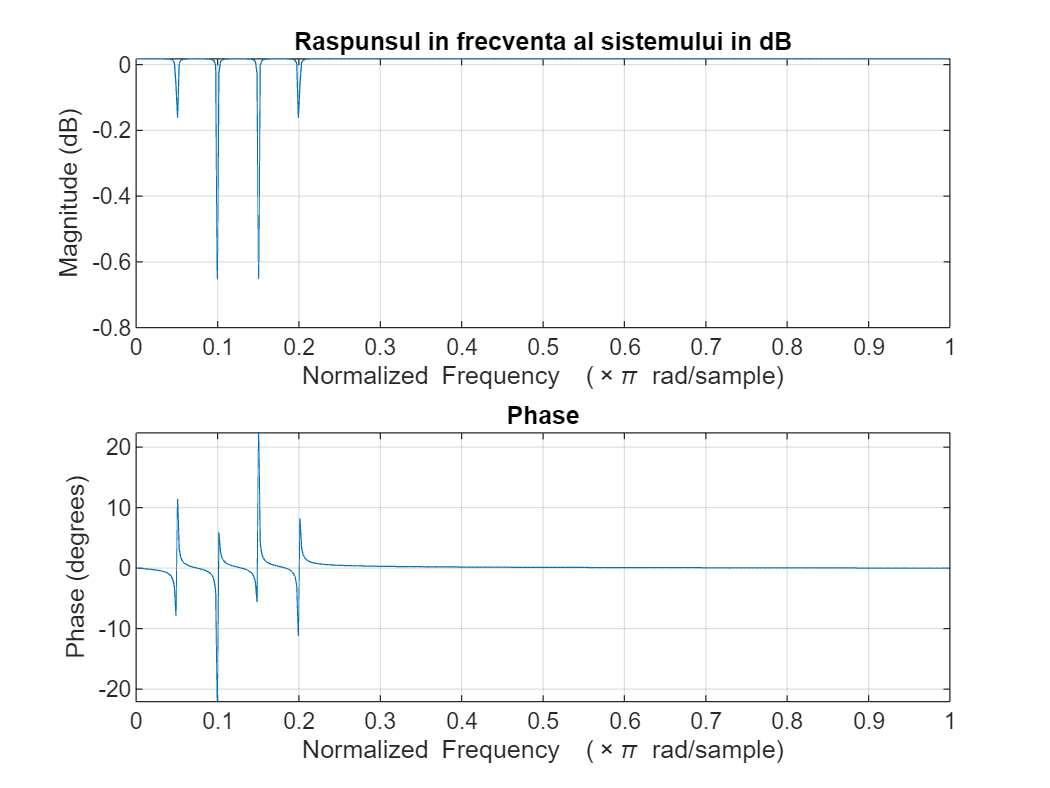


% Reprezentarea raspunsului in frecventa (dB)
figure();
freqz(b,a);
title('Raspunsul in frecventa al sistemului in dB');

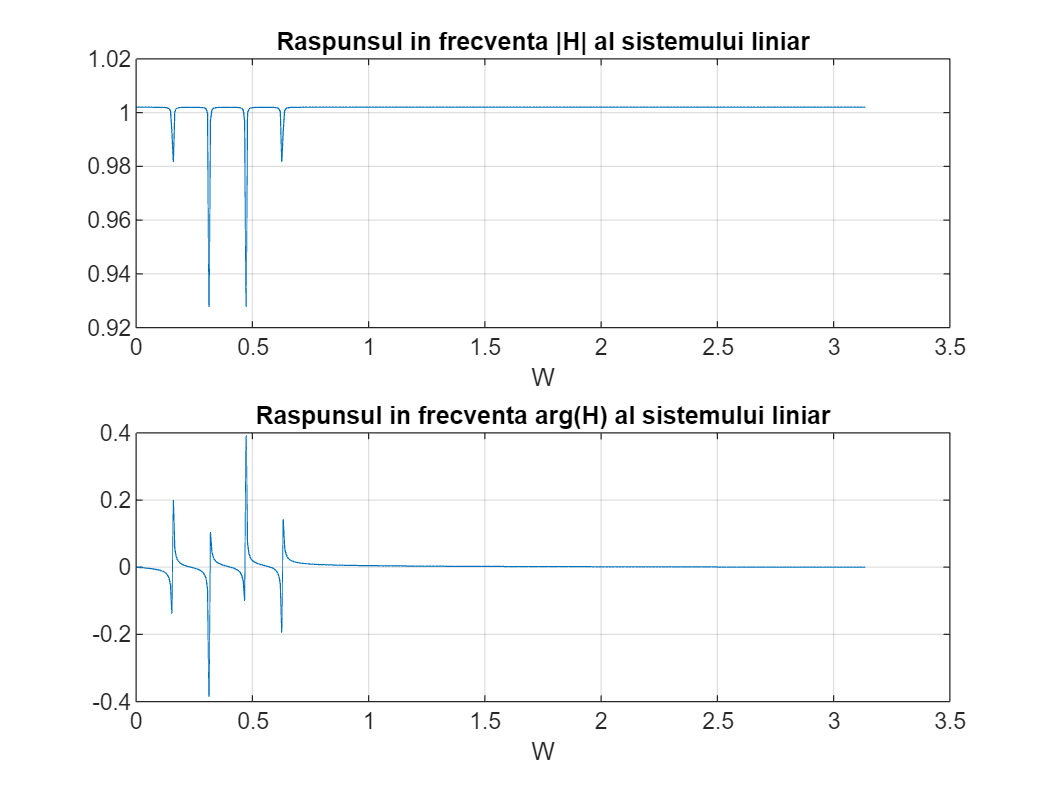


% Aflarea functiei de transfer
[H, W] = freqz(b, a);

% Reprezentarea raspunsului in frecventa (linear)
figure();
subplot(2, 1, 1), plot(W, abs(H)), grid;
title('Raspunsul in frecventa |H| al sistemului liniar');
xlabel('W');
subplot(2, 1, 2), plot(W, angle(H)), grid;
title('Raspunsul in frecventa arg(H) al sistemului liniar');
xlabel('W');


% Raspunsul la impuls al sistemului
figure();
impz(b, a);
grid on;
title('Raspunsul la impuls al sistemului');

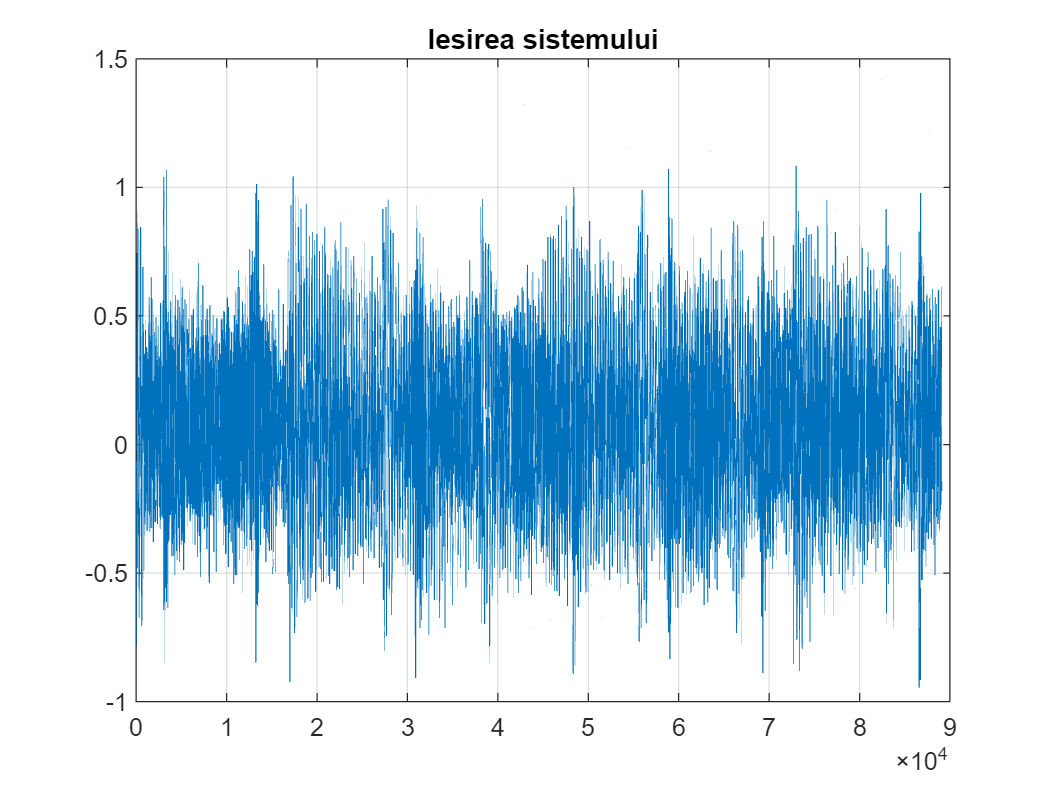


% Iesirea sistemului cand la intrare este s(n)
y = filter(b, a, s);
figure();
plot(n, y); 
grid on;
title('Iesirea sistemului');


% Spectrograma semnalului de la iesire
figure();
spectrogram(y, 512, 256, Nfft, Fss, 'yaxis');
colormap("jet");
title('Spectrograma semnalului de la iesire');

%% ASCULTA INTRAREA SISTEMULUI

sunet_intrare = audioplayer(w, Fss);
play(sunet_intrare);

% Apasa butonul
 

%% ASCULTA IESIREA SISTEMULUI

sunet_iesire = audioplayer(y, Fss);
play(sunet_iesire);

% Apasa butonul
 